# Performance evaluation: ROC curves

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared two trained classifiers with you and some previously unseen testing data. You can assume the data has been properly prepared:

clear all;
load('classifiers.mat', 'm_knn', 'm_nb', 'test_examples', 'test_labels');

Your task is to analyse the True Positive Rate (TPR) and False Positive Rate (FPR) for each classifier in order to make a decision about which one is performing best.

Marks are available for:

- Using each classifier to predict labels and associated likelihood scores for the test data [4 marks]

- Computing the TPR for each classifier, taking "Malignant" as the positive class [3 marks]

- Computing the FPR for each classifier, taking "Malignant" as the positive class [3 marks]

- Generating a Receiver Operating Characteristic (ROC) curve for each classifier, taking "Malignant" as the positive class, and plotting them together on a single graph with a legend and labelled axes [4 marks]

- Deciding on the best classifier based on a sensible quantitative comparison between the ROC curves [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

%use m_nb classifier to predict labels for the test data
[predictions, scores] = m_nb.predict(test_examples)

predictions = 142×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 


scores =     0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    1.0000    0.0000


% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     83     2
     4    53


order = 2×1 categorical array
     Benign 
     Malignant 


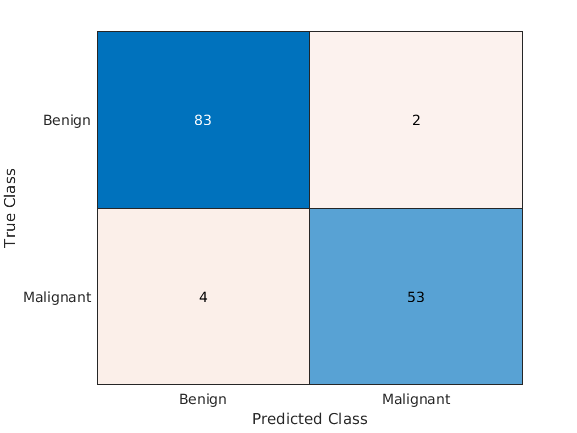


% outputs a labelled chart of the confusion matrix, the diagonal from top
% left down to bottom right are the labels that were predicted correctly
% and the diagonals from bottom left to top right are the labels that were
% predicted incorrectly, the value given represents how many times that
% label was predicted
c_chart = confusionchart(test_labels, predictions);


%calculate overall classification accuracy
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.9577


%calculate TPR
TP = c(2,2); %find true positives by indexing confusion matrix
FN = c(2,1); %find false negatives by indexing confusion matrix
TPR = (TP)/(TP+FN) %calculate TPR by calculating the proportion of positive examples that where correctly classified

TPR = 0.9298


%calculate FPR
FP = c(1,2); %find false positives by indexing confusion matrix
TN = c(1,1); %find true negatives by indexing confusion matrix
FPR = (FP)/(FP+TN) %calculate FPR by calculating the proportion of negative examples that incorrectly classified as positive

FPR = 0.0235


%create ROC curve
[x,y,~,AUC] = perfcurve(test_labels, scores(:, 2), m_nb.ClassNames(2));
AUC

AUC = 0.9769

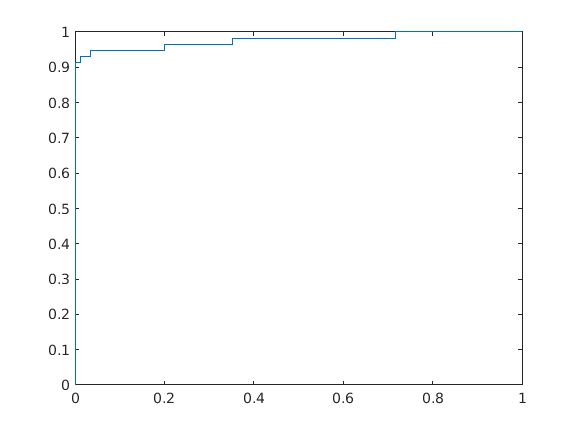

plot(x,y)


%use m_knn classifier to predict labels for the test data
[predictions, scores] = m_knn.predict(test_examples)

predictions = 142×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 


scores =      0     1
     0     1
     1     0
     1     0
     0     1
     0     1
     1     0
     1     0
     0     1
     1     0


% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     84     1
     4    53


order = 2×1 categorical array
     Benign 
     Malignant 


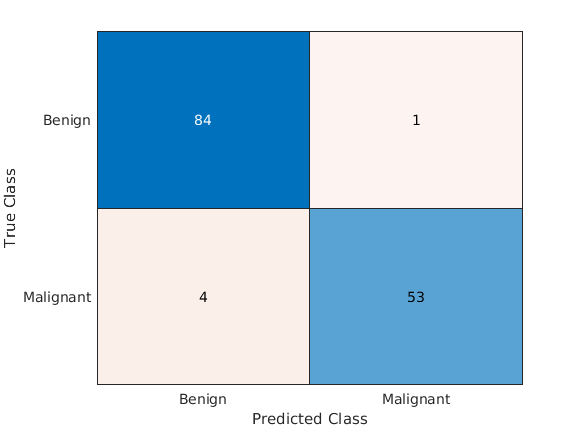


% outputs a labelled chart of the confusion matrix, the diagonal from top
% left down to bottom right are the labels that were predicted correctly
% and the diagonals from bottom left to top right are the labels that were
% predicted incorrectly, the value given represents how many times that
% label was predicted
c_chart = confusionchart(test_labels, predictions);


%calculate overall classification accuracy
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.9648


%calculate TPR
TP = c(2,2); %find true positives by indexing confusion matrix
FN = c(2,1); %find false negatives by indexing confusion matrix
TPR = (TP)/(TP+FN) %calculate TPR by calculating the proportion of positive examples that where correctly classified

TPR = 0.9298


%calculate FPR
FP = c(1,2); %find false positives by indexing confusion matrix
TN = c(1,1); %find true negatives by indexing confusion matrix
FPR = (FP)/(FP+TN) %calculate FPR by calculating the proportion of negative examples that incorrectly classified as positive

FPR = 0.0118


%create ROC curve
[x,y,~,AUC] = perfcurve(test_labels, scores(:, 2), m_nb.ClassNames(2));
AUC

AUC = 0.9854

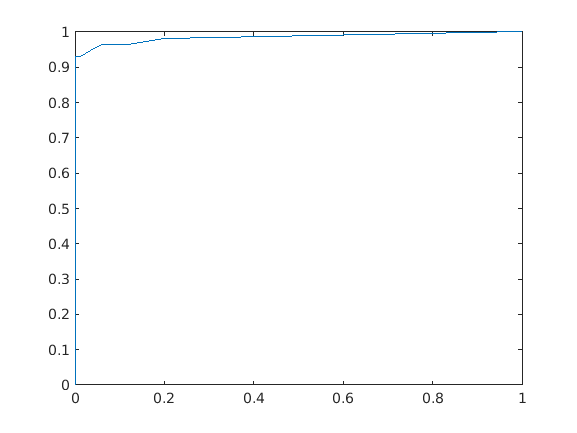

plot(x,y)


%I believe the best classifier to use in this case would be the KNN
%classifier, both TPR values are the same but for the KNN the FPR value is
%closer to 0, also the KNN ROC curve has a larger value for the area under
%the curve (AUC) meaning it is better at identifyting positive examples